# Example 4.5: Random and Nonrandom Sample Sequences

Note: this script reproduces Example 4.5 (Section 4.3) of **Statistics for Chemical Engineers**: a random sample of N(0,1) and a sample selected with a hidden mechanism. Victor Z UW-Madison, 2020 random and biased samples

clc; clear all; close all hidden; 

## Random sample

generate random observations

rng(0);
S = 100;
x = normrnd(0,1,S,1);
xx=1:1:S;

## Nonrandom sample

generate non-random observations use mechanism to discard sample if above threshold

S2 = 200;
xt = normrnd(0,1,S2,1);
for k=1:S2
   if xt(k)<=1
      x2(k)=xt(k);
   end
end
x2=x2(x2~=0);
x2=x2(1:S);

## Means and bias

compute means for both

mx=linspace(mean(x),mean(x),S);
mx2=linspace(mean(x2),mean(x2),S);

% compute bias
bias1=mean(x'-mx)

bias1 =    1.7764e-17

bias2=mean(x2-mx)

bias2 =   -4.3503e-01

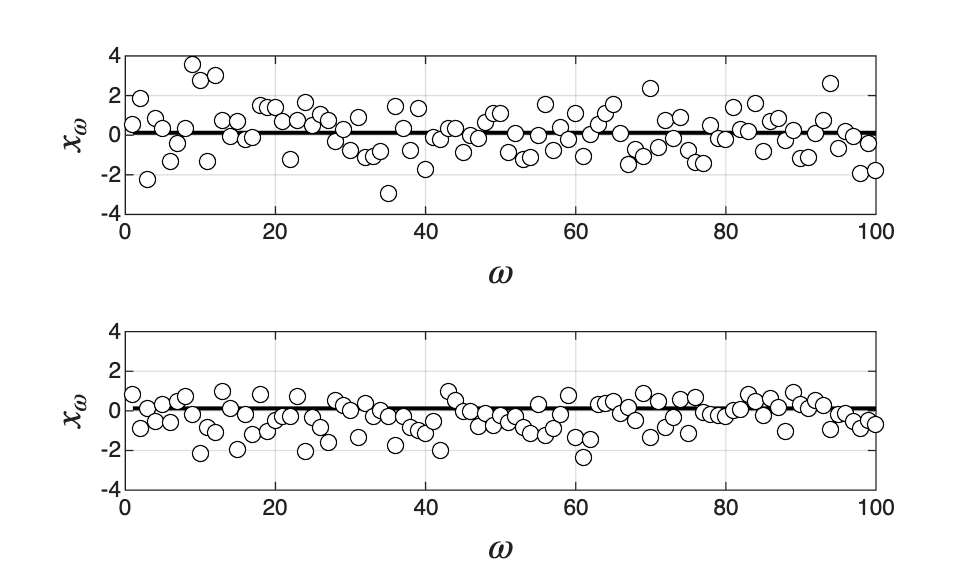


% display sequences
figure(1)
subplot(2,1,1)
plot(xx,mx,'black','LineWidth',1.5)
hold on
plot(x,'blacko','MarkerFaceColor','w','MarkerEdgeColor','black')
grid on
axis([0 S -4 4])
xlabel('$\omega$','Interpreter','latex','FontSize',14)
ylabel('$x_\omega$','Interpreter','latex','FontSize',14)
subplot(2,1,2)
plot(xx,mx,'black','LineWidth',1.5)
hold on
plot(xx,x2,'o','MarkerFaceColor','w','MarkerEdgeColor','black')
grid on
axis([0 S -4 4])
xlabel('$\omega$','Interpreter','latex','FontSize',14)
ylabel('$x_\omega$','Interpreter','latex','FontSize',14)
print -depsc ch4_random_sample.eps

## Note

As in the book, discarding observations above a threshold biases the sample: its mean is shifted toward negative values (bias of about -0.43).